clear all;  close all;
addpath('MatlabSourceFiles');


%I = imread('cameraman.tif');
I = rgb2gray(imread('corners.png'));

% Convert to double
I = double(I);

% Re-scale intensities to range 0 to 1
I = I/255;

% Create Gaussian pyramid
nooctaves = 4;
pyramid{1}.I = I; % Initialize pyramid with original image

% Use impyramid decomposition from Computer Vision Toolbox

for octave = 2:nooctaves
  pyramid{octave}.I = impyramid(pyramid{octave-1}.I, 'reduce');
end

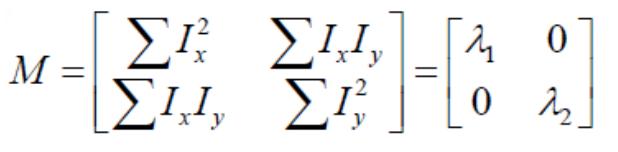

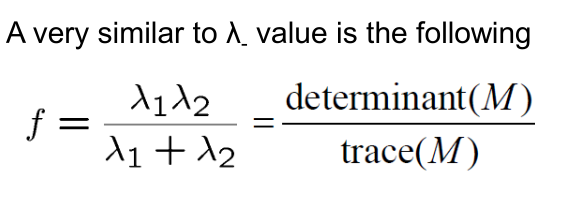

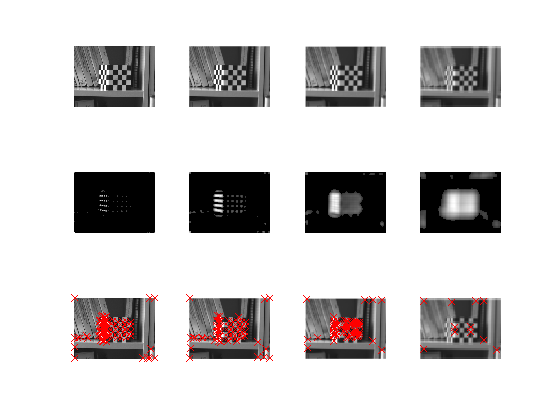

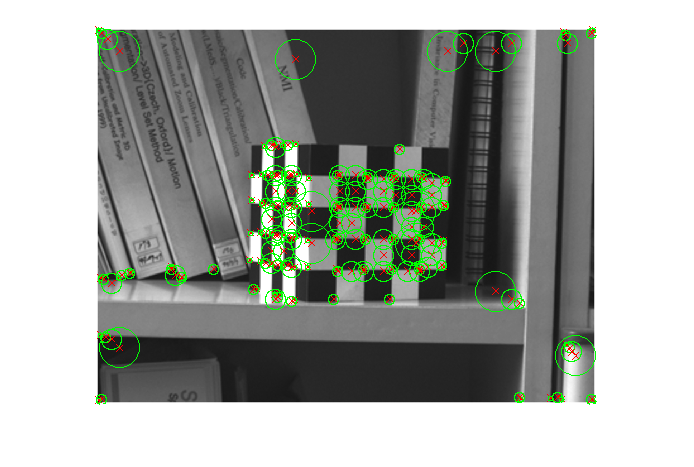

% Harris
figure(1)
figure(2)
imshow(pyramid{1}.I);
hold on;

for i = 1:nooctaves,
    I = pyramid{i}.I;
    [Ix,Iy] = gradient(I);
    lambda_max = zeros(size(I));
    lambda_min = zeros(size(I));
    Ixx = imfilter(Ix.^2,fspecial('gaussian',10,3));
    Iyy = imfilter(Iy.^2,fspecial('gaussian',10,3));
    Ixy = imfilter(Ix.*Iy,fspecial('gaussian',10,3));
    R = zeros(size(I));
    for x = 1:size(I,1)
        for y = 1:size(I,2)
            % Exercise: Find the Harris corner measure (Harris operator), R
            M = [
                Ixx(x,y), Ixy(x,y);
                Ixy(x,y), Iyy(x,y)
                ];

            [~,eigens] = eig(M);
            
            R(x,y) = det(eigens)/trace(eigens);
        end
    end
    
    % Find local maxima
    R(R <= 0.2*max(R(:))) = 0; % Discard local maxima less than 20% of the global maximum
    M = imregionalmax(R);
    
    % Show each pyramid level seperably
    figure(1)
    subplot(3,nooctaves,i)
    imshow(I)
    subplot(3,nooctaves,nooctaves+i)
    show_norm_image(R);
    subplot(3,nooctaves,2*nooctaves+i)
    imshow(I);
    hold on;
    showFeatures( M, 1, 0 )
    
    % Show all pyramid levels combined
    figure(2)
    showFeatures( M, i, 1 )
end

The middle row shows the corner response function (R), and the bottom row shows the detected corners. How are the corners detected from R?